% Get gyro and accel values from MATLAB realistic IMU
accelVals = readmatrix('C:\Users\anthe\OneDrive - University of Pretoria\UP\Final Year\EPR 400\IMU Testing for Proposal\MATLAB\MATLAB_IMU_accelerometer.xlsx')*(-9.807); % <- m/s^2
gyroVals = readmatrix('C:\Users\anthe\OneDrive - University of Pretoria\UP\Final Year\EPR 400\IMU Testing for Proposal\MATLAB\MATLAB_IMU_gyroscope.xlsx'); % <- deg/s;

% Step time
fs = 6664; % Hz <- IMU has 6664 Hz <- 100 Hz test
ts = 1/fs;
t_len = 5; 
n = 10;
totalNumSamples = n*(t_len/ts);   
t = (0:(totalNumSamples-1)).'/fs;

roll_drift_max = 3;
roll_drift_min = 1;
step_roll = 0.1;

roll_drift_val = 1.5;

pitch_drift_max = 2;
pitch_drift_min = 0;
step_pitch  = 0.1

step_pitch = 0.1000

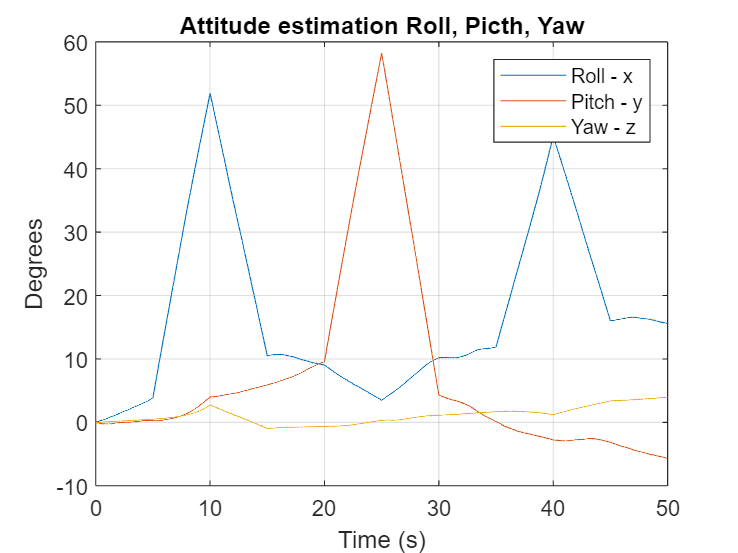


pitch_drift_val = 0.2;

yaw_drift_max = 2;
yaw_drift_min = 0;
step_yaw = 0.1;

yaw_drift_val = 0;

% Correct gyro drift
for i = 1:totalNumSamples
    gyroVals(i, :) = [(gyroVals(i, 1) - roll_drift_val) (gyroVals(i, 2) - pitch_drift_val) 0.1];
    % gyroVals(i, :) = [gyroVals(i, 1)-1 gyroVals(i, 2)-1 gyroVals(i, 3)-1];
end

gyroVals = gyroVals*(pi/180); % <- rad/s

% Initial quaternion 
Q(1,:) = [1 0 0 0]; % <- [q0 q1 q2 q3] <- initial value

% Attitude initialisation
theta = asin(-2*(Q(1,2)*Q(1,3) - Q(1,1)*Q(1,3)));
phi = atan(2*(Q(1,1)*Q(1,2) + Q(1,3)*Q(1,4))/(Q(1,1)^2 - Q(1,2)^2 - Q(1,3)^2 + Q(1,4)^2));
psi = atan(2*(Q(1,1)*Q(1,4) + Q(1,2)*Q(1,3))/(Q(1,1)^2 + Q(1,2)^2 - Q(1,3)^2 - Q(1,4)^2));

attitude = zeros(totalNumSamples, 3);
attitude(1,:) = [theta phi psi]*(180/pi); % <- roll pitch yaw for initial quaternion

acceleration = zeros(totalNumSamples, 3);
gyroscope = zeros(totalNumSamples, 3);

gyroMeasurementError = 0.00293*(pi/180); % (70*10^(-3)) <- resolution from gyroscope
B = sqrt(3/4)*gyroMeasurementError;

%% Main loop 
for i = 2:totalNumSamples 
    qMagdwick = Magdwick(accelVals(i,:), gyroVals(i,:), Q(i-1, :), B, ts);
    Q(i, :) = qMagdwick;

    % Plot roll, pitch, yaw
    q0 = qMagdwick(1);
    q1 = qMagdwick(2);
    q2 = qMagdwick(3);
    q3 = qMagdwick(4);

    theta = asin(-2*(q1*q2 - q0*q2)); % <- roll (y)
    phi = atan(2*(q0*q1 + q2*q3)/(q0^2 - q1^2 - q2^2 + q3^2)); % <- pitch (x)
    psi = atan(2*(q0*q3 + q1*q2)/(q0^2 + q1^2 - q2^2 - q3^2)); % <- yaw (z)

    attitude(i, :) = [theta phi psi]*(180/pi);

end

% Plot results IMU
figure(8)
plot(t, attitude)
xlabel('Time (s)')
ylabel('Degrees')
title('Attitude estimation Roll, Picth, Yaw')
legend('Roll - x','Pitch - y','Yaw - z')
grid on


% Magdwick Filter Function

function quat = Magdwick(acc, gyro, q, B, ts) % <- current quat determined from prev estimation
    q0 = q(1);
    q1 = q(2);
    q2 = q(3);
    q3 = q(4);
    acc =  acc/norm(acc);	% normalise magnitude

    % q0A = qA(1);
    % q1A = qA(2);
    % q2A = qA(3);
    % q3A = qA(4);

    % Gradient decent algorithm corrective step
    F = [2*(q1*q3 - q0*q2)-acc(1);
         2*(q0*q1 + q2*q3)-acc(2);
         2*(0.5 - q1^2 - q2^2)-acc(3)];

    J = [-2*q2 2*q3 -2*q0 2*q1;
          2*q1 2*q0 2*q3 2*q2;
          0 -4*q1 -4*q2 0];

    step = (J'*F);
    step = step / norm(step);	% normalise step magnitude

    % Fusion algorithm
    qDot = 0.5*quatmultiply([q0 q1 q2 q3],[0 gyro(1) gyro(2) gyro(3)]) - B*step';

    % Integrate to yield quaternion
    q = q + qDot*ts; % <- new estimate
    quat = q / norm(q); % normalise quaternion and return value of new orientation estimate
end

